# Curve Generation Simulation

## Function import

% RUN in file directory
addpath(genpath("../utils/"), genpath("../curve_generation/"));

## Initialize

clear all; clc;


% simulation pose
% points = [
%     0, 0, deg2rad(0); 
%     10, 10, deg2rad(-90); 
%     20, 5, deg2rad(60);
%     30, 10, deg2rad(120);
%     35, -5, deg2rad(30);
%     25, -10, deg2rad(-120);
%     15, -15, deg2rad(100);
%     0, -10, deg2rad(-90)
% ];

points = [
    -3, 3, deg2rad(120);
    10, -7, deg2rad(30);
    10, 13, deg2rad(30);
    20, 5, deg2rad(-25);
    35, 10, deg2rad(180);
    32, -10, deg2rad(180);
    5, -12, deg2rad(90)
];

% generator
% generator_name = "polynomial_curve";
% generator_name = "bezier_curve";
% generator_name = "bspline_curve";
% generator_name = "cubic_spline_curve";
% generator_name = "dubins_curve";
generator_name = "reeds_shepp_curve";

## Curve Generation

generator = str2func(generator_name);
path = generator(points);

## Visualization

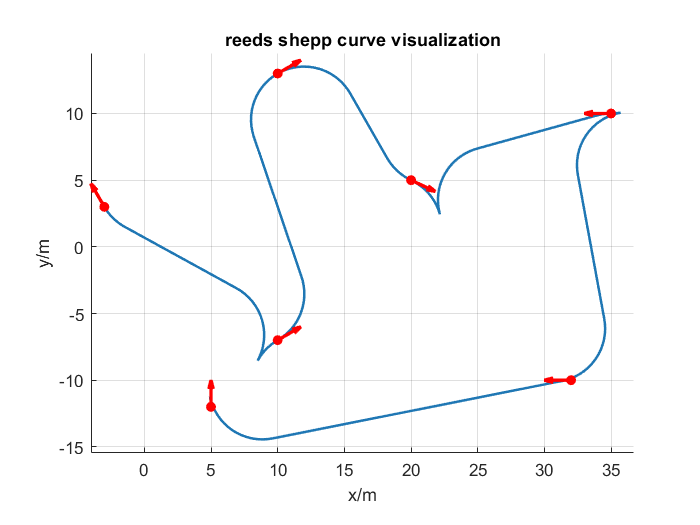

hold on
grid on
plot(path(:, 1), path(:, 2), "LineWidth", 1.5, "Color", "#1f77b4");

for i=1:length(points)
    plot_arrow(points(i, 1), points(i, 2), points(i, 3), "red"); 
end

title_name = strrep(generator_name, "_", " ");
title(title_name + " visualization");

axis equal;
xlim([min(path(:, 1)) - 1, max(path(:, 1)) + 1]);
ylim([min(path(:, 2)) - 1, max(path(:, 2)) + 1]);
xlabel("x/m"); ylabel("y/m");
hold off